## Лабораторная работа №7

### Задание: постройте двумерные, трёхмерные, а также контурные графики предложенных "тестовых" функций. Маркерами обозначьте точки экстремума, классифицируйте их. Для контурных графиков выведите только значимые линии уровня, подпишите численные значения уровня.

Фокус: функции Швефеля и Растригина определяются суммой одномерных функций. Чтобы не решать каждую задачу отдельно, создаём m - функцию, которая сделает всю грязную работу за нас. На вход подаётся анонимная функция и предел по одномерному x, на выход получаем то, что нужно.

Функция countAndDraw. P.S Если значения в каждой точке для пары x1, x2 определяются как сумма одномерных функций: f(x1) + f(x2), то справедливо будет нахождение значений минимумов как сумма одномерных минимумов.

clc; clear;
Schwefel = @(x) 418.9829 + (- x .* sin( sqrt( abs(x) ) ) );
Rastrigin = @(x) 10 + (x.^2 - 10 .* cos(2 * pi * x));

Функции задали. Можем отрисовывать.

Для 1d-функции минимум находится при x = 4.209687e+02, y = 1.272757e-05


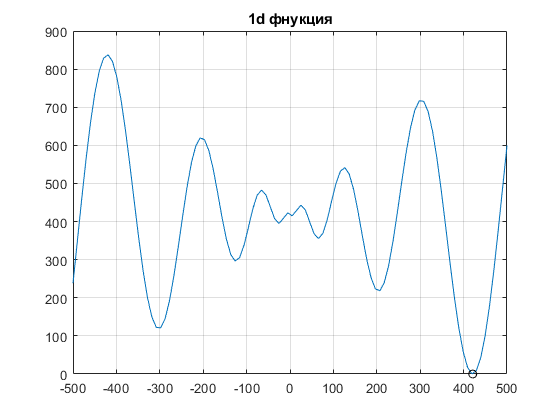

Для 2d-функции минимум находится при x1 = 4.209687e+02, x2 = 4.209687e+02, y = 2.545513e-05


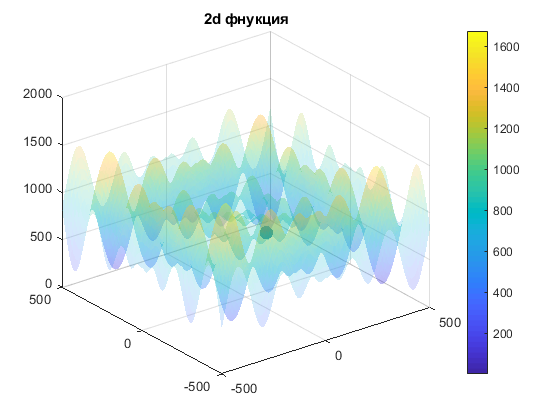

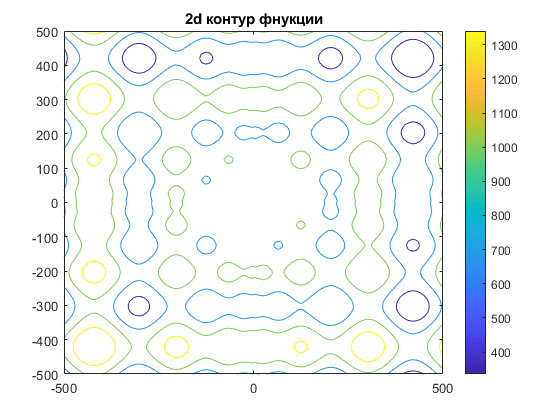

countAndDraw(Schwefel, 500);

Аналогично для Растригина:

Для 1d-функции минимум находится при x = 1.110223e-16, y = 0


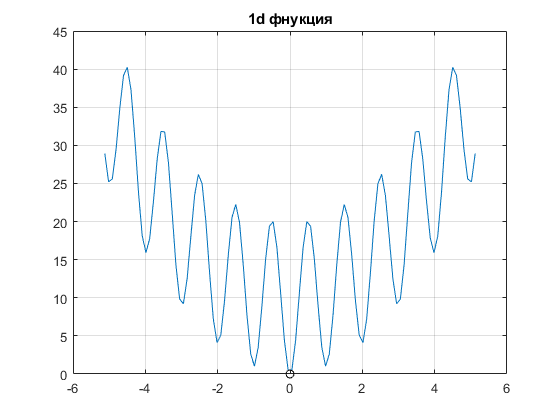

Для 2d-функции минимум находится при x1 = 1.110223e-16, x2 = 1.110223e-16, y = 0


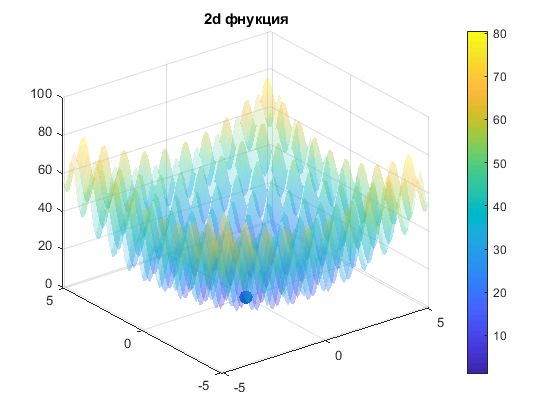

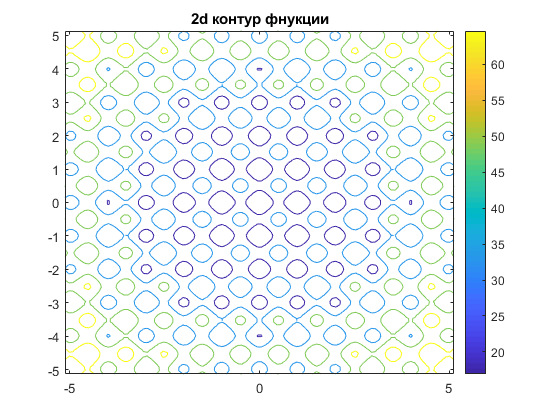

countAndDraw(Rastrigin, 5.12);

Функция Розенброка:

Rosenbrock = @(x1,x2) 100 * (x2 - x1.^2).^2 + (x1 - 1) .^2;
x1 = linspace(-1.5, 1.5, 300);
x2 = x1;

Задаём функцию Розенброка и пределы счёта/отрисовки

[X1, X2] = meshgrid(x1, x2);
limit = X1.^2 + X2.^2;
inLimit = limit;
limit(limit > 2) = NaN; limit(limit < 2) = 1;
inLimit(inLimit <= 2) = NaN; inLimit(inLimit > 2) = 1;

Создаём mesh сетку и задаём матрицу limit, где просчитаны значения диска.

Далее, если значения попадают в "диск", они остаются в матрице inLimit, если вне диска - в матрице limit. 

Остальные значения заменил на NaN, т.к. не числа не строятся.

res = Rosenbrock(X1, X2);

toSurf = res .* limit;
notToSurf = res .* inLimit;

Посчитали глобального Розенброка, создаём матрицы для отрисовки. Логическое условие - матрица limit.

(NaN * число) = NaN. Т.к. остальные числа в матрицах пределов равны 1, то на конечный результат умножение не повлияет.

[row, col] = find(res == min(min(res)));
location = [x1(row), x1(col)];
RosenbrockMin = @(x) 100 * (x(2) - x(1).^2).^2 + (x(1) - 1) .^2;
location = fminsearch(RosenbrockMin, location);

Поиск минимума здесь немного сложнее. Сначала я нашёл минимальный элемент в массиве Розенброка и его индексы.

Затем по индексам нашел численные значения на осях. Их прогнал через fminsearch, которая вблизи точки нашла точный минимум.

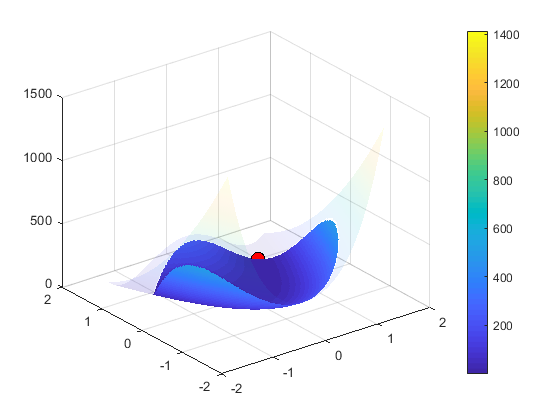

figure;
surf(X1, X2, toSurf, 'EdgeColor', 'none'); colorbar(); hold on;
surf(X1, X2, notToSurf, 'EdgeColor', 'none', 'FaceAlpha', 0.1); hold on;
scatter3(location(1), location(2), RosenbrockMin(location), 'filled', 'SizeData', 100, 'MarkerEdgeColor','k', 'MarkerFaceColor', 'r');

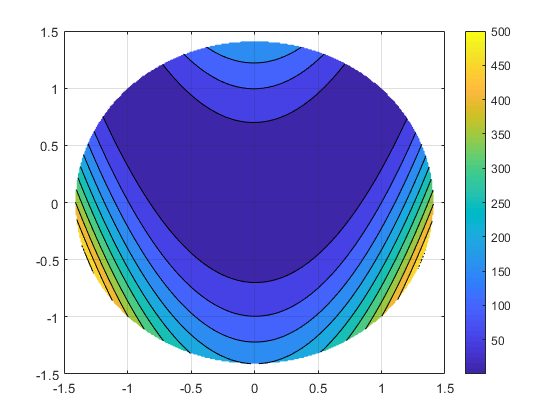

figure;
contourf(X1, X2, toSurf); grid on;
colorbar();

Здесь просто построение. То, что вне диска - прозрачное. То, что внутри - закрашенное.

Функция countAndDraw.

Единственное, на чём можно остановиться - поиск минимума.

Для приблизительного нахождения берётся точка из вычисленного результативного массива, для уточнения минимума - функция fminsearch,

которая ищет вблизи минимума из массива.

function countAndDraw(handler, x)
    xLine = linspace(-x, x, 100);
    
    %поиск минимума
    res = handler(xLine);
    [~, index] = min(res);    
    minimum = fminsearch(handler, xLine(index));

    %1d - график
    figure;
    plot(xLine, res);
    grid on; hold on;
    plot(minimum, handler(minimum), 'ko');
    fprintf('Для 1d-функции минимум находится при x = %d, y = %d\n', minimum, handler(minimum));
    title('1d фнукция')

    %2d - график
    figure;
    [X1, X2] = meshgrid(xLine, xLine);
    res3 = handler(X1) + handler(X2);
    surf(X1, X2, res3, "EdgeColor","none", "FaceAlpha", .2);
    colorbar();
    
    grid on; hold on;
    scatter3(minimum, minimum, 2 * handler(minimum), 'filled', 'SizeData', 100);
    fprintf('Для 2d-функции минимум находится при x1 = %d, x2 = %d, y = %d\n', minimum, minimum, 2 * handler(minimum));
    title('2d фнукция')
    
    %контур
    figure;
    contour(X1, X2, res3, 4); hold on;
    %contour(minimum, minimum, 2 * handler(minimum), 1, 'LineWidth', 4);
    colorbar();
    title('2d контур фнукции')
end

#### Вывод: овладели средствами построения 3D графиков (поверхностей и пр.) на примере тестовых функций.